Lab1_c

konstanten

clear all;
f0=1;   % Grundfreqeunz in Hertz
n=5;    % Anzahl der Harmonischen
y0=1;    % Amplitude 
w=0.5;  % Breite der Rechteckfunktion in sec
 
fs= 8000 * f0;    %Shannon-Theory (Minimu 2* f0)
nCycl = 2;    % Anzahl der kompletten Zyklen der Sinus-Welle
 
 
% Abtastzeiten
t=-(nCycl*1/f0):1/fs:(nCycl*1/f0)-1/fs; %time base

periodische rechteckfunktion

figure(1)
 
x = rectpuls(t+1.75,w) -rectpuls(t+1.25,w) + rectpuls(t+0.75,w) ... 
    - rectpuls(t+0.25,w)+ rectpuls(t-0.25,w) - rectpuls(t-0.75,w) ... 
    + rectpuls(t-1.25,w) - rectpuls(t-1.75,w) ;
plot(t,x,'LineWidth',1.0), grid; 
hold on

periodische rechteckfunktion (ersten 5 harmonischen)

data = zeros(size(t));
  y0=4*y0/pi;
for k = 0:n-1
  ak=y0/(2*k+1);
  data = data + ak*sin(2*pi*(2*k+1)*f0*t);
end
 
plot(t,data,'LineWidth',1.0), grid; 
title('Rechteckfunktion durch sinus-Funktionen angenähert')
xlabel('Zeit (t)')
ylabel('Signal x(t)')
%xlim ([0 0.1])
hold on;

erzeugen/plotten ersten 5 harmonischen

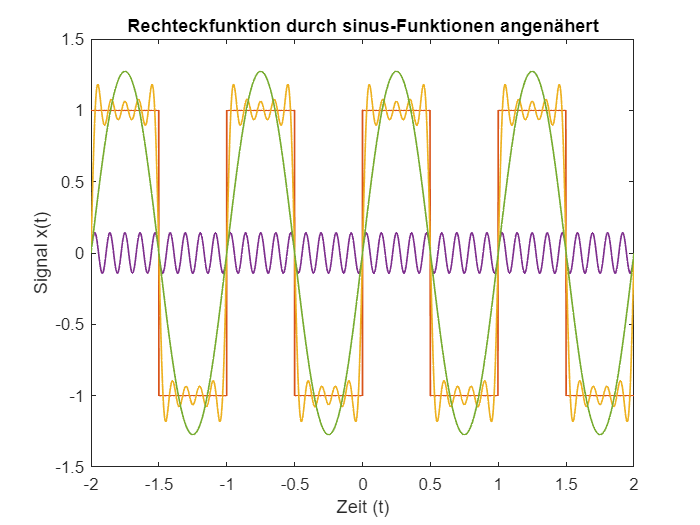

k=n-1;
 
data0=y0*sin(2*pi*f0*t);
dataN=y0/(2*k+1)*sin(2*pi*(2*k+1)*f0*t);
 
plot(t,dataN,'LineWidth',1.0);
plot(t,data0,'LineWidth',1.0);

rechteckfunktion mit f0 =440hz

f0=440;   % Grundfreqeunz in Hertz
nCycl = 440;    % Anzahl der kompletten Zyklen der Sinus-Welle
 
 
% Abtastzeiten
t=-(nCycl*1/f0):1/fs:(nCycl*1/f0)-1/fs; %time base
data = zeros(size(t));
  y0=4*y0/pi;
for k = 0:n-1
  ak=y0/(2*k+1);
  data = data + ak*sin(2*pi*(2*k+1)*f0*t);
end
 
%audiowrite('wave/Lab1_c_Periodic_Recteck_Function_440.wav', data ,fs); %export file
%[y,fs] = audioread('wave/Lab1_c_Periodic_Recteck_Function_440.wav'); 
%sound(y,fs);               % Signal abspielen